# Lab - Boundary value problems 2

**Topics: **finite-difference method for linear equations, finite-difference method for non-linear equations

## Water table height

clear, clc, format compact

Given: $K\bar{h} \;\frac{d^2 h}{{\textrm{dx}}^2 }+N=0$

Solve for the height of the water table for x = 0 to 1000 m where h(0)=10 m and h(1000)=5 m. Use the following parameters: K=1 m/d and N=0.0001 m/d. Use the average of the boundary conditions as the average height ($\bar{h}$). $\Delta x=200\;m$

### Set up variables

k = 1;
n = 0.0001;

x0 = 0;
xf = 1000;

h0 = 10;
hf = 5;
hbar = (h0+hf)/2;

dx = 200;

### **Analytical solution**


$$K\bar{h} \;\frac{d^2 h}{{\textrm{dx}}^2 }+N=0$$


syms h(x)
Dh = diff(h);
ode = k*hbar*diff(h, x, 2)+n == 0;

cond1 = h(x0) == h0;
cond2 = h(xf) == hf;
conds=[cond1 cond2];
solution(x)=dsolve(ode, conds)

$$solution(x) = -\frac{x^{2}}{150000}+\frac{x}{600}+10$$

### Set up system


$$h_{i-1} -2h_i +h_{i+1} =-\frac{N\Delta x^2 }{K\bar{h} }$$


c = -n*dx^2/(k*hbar)

c = -0.5333


$$\begin{array}{l}
-2h_1 +h_2 =C-h_0 \\
h_1 -2h_2 +h_3 =C\\
h_2 -2h_3 +h_4 =C\\
h_3 -2h_4 =C-h_5 
\end{array}$$


A = [-2  1  0  0;
      1 -2  1  0;
      0  1 -2  1;
      0  0  1 -2];
% or
n = 4;
A = diag(ones(1,n)*-2) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1);

b = [c-h0;c;c;c-hf];


### Numerical solution

H = A\b;

### Plot height

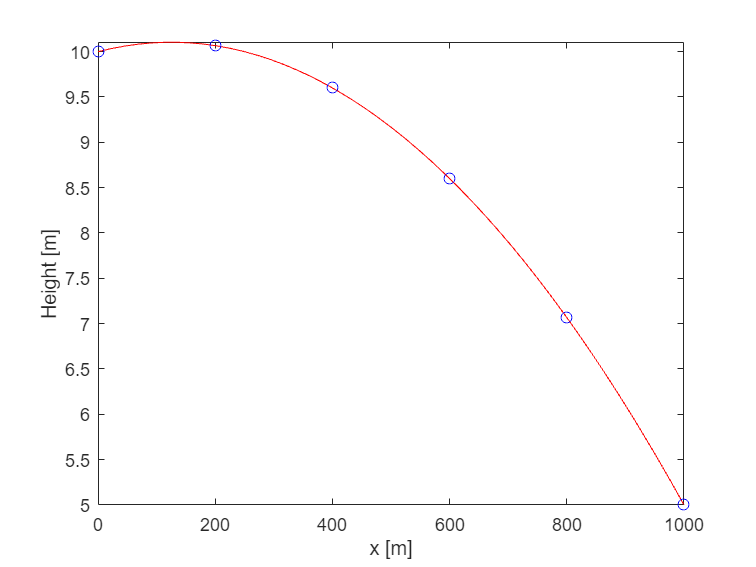

xVal = x0:dx:xf;
hVal = [h0;H;hf];
fplot(solution,[x0 xf],'r')
hold on;
plot(xVal,hVal,'bo')
xlabel 'x [m]'
ylabel 'Height [m]'

## Golden Gate Bridge cable position boundary value problem

clear, clc

Let u(x) denote the position of the centerline of the cable between the two towers of the Golden Gate Bridge.  The boundary value problem that determines the shape of the cable is: $\frac{d^2 u}{{\textrm{dx}}^2 }=\frac{w}{T}\sqrt{1+{\left(\frac{\textrm{du}}{\textrm{dx}}\right)}^2 },u\left(0\right)=h,u\left(L\right)=h$.

If w, the weight per length of cable is 48.7 kN/m, T, the horizontal component of tension, is 240 MN, L, the distance between the two towers, is 1280 m, and h, the height of the towers, is 152 m

**Determine the position of the cable centerline every 128 meters along the bridge.**

### Set up variables

w = 48.7; % weight per length of cable [kN/m]
T = 240; % horizontal component of tension [MN]
T_kN = T*1000;

h = 152; % height of towers above  the deck [m]
L = 1280; % lenght of center span of bridge [m]

x0 = 0;  % initial location along bridge [m]
xf = L;  % final position along the bridge [m]
u0 = h; % initial position of centerline of cable on suspension bridge  [m]
uf = h; % final position of centerline of cable on suspension bridge [m]
dx = 128; % step size [in seconds]
x_finite = x0:dx:xf;
n = length(x_finite);
u_finite = linspace(uf,uf,n);



### **Analytical solution MATLAB - Cannot find unique solution**

syms u(x)
Du = diff(u);
ode = diff(u,x,2) == w/T_kN*sqrt(1+Du^2);
cond1 = u(x0) == u0;
cond2 = u(xf) == uf;
conds=[cond1 cond2];
analyticalNonlinear(x)=dsolve(ode, conds)

$$analyticalNonlinear(x) = \left(\begin{array}{c} \frac{{\mathrm{e}}^{-\frac{1871575909145115\,C_{2}}{4611686018427387904}-\frac{1871575909145115\,x}{9223372036854775808}}\,\left({\left(9223372036854775808\,C_{1}-4611686018427387904\,{\mathrm{e}}^{\frac{1871575909145115\,C_{2}}{4611686018427387904}+\frac{1871575909145115\,x}{9223372036854775808}}\right)}^{2}-85070591730234615865843651857942052864\,{C_{1}}^{2}+85070591730234615865843651857942052864\right)}{17262240905260108166976990263377920}\\ \frac{{\mathrm{e}}^{-\frac{1871575909145115\,C_{4}}{4611686018427387904}-\frac{1871575909145115\,x}{9223372036854775808}}\,\left({\left(9223372036854775808\,C_{3}-4611686018427387904\,{\mathrm{e}}^{\frac{1871575909145115\,C_{4}}{4611686018427387904}+\frac{1871575909145115\,x}{9223372036854775808}}\right)}^{2}-85070591730234615865843651857942052864\,{C_{3}}^{2}+85070591730234615865843651857942052864\right)}{17262240905260108166976990263377920}\\ \frac{{\mathrm{e}}^{\frac{1871575909145115\,x}{9223372036854775808}-\frac{1871575909145115\,C_{5}}{4611686018427387904}}\,\left({\left(9223372036854775808\,C_{6}-4611686018427387904\,{\mathrm{e}}^{\frac{1871575909145115\,C_{5}}{4611686018427387904}-\frac{1871575909145115\,x}{9223372036854775808}}\right)}^{2}-85070591730234615865843651857942052864\,{C_{6}}^{2}+85070591730234615865843651857942052864\right)}{17262240905260108166976990263377920}\\ \frac{{\mathrm{e}}^{\frac{1871575909145115\,x}{9223372036854775808}-\frac{1871575909145115\,C_{7}}{4611686018427387904}}\,\left({\left(9223372036854775808\,C_{8}-4611686018427387904\,{\mathrm{e}}^{\frac{1871575909145115\,C_{7}}{4611686018427387904}-\frac{1871575909145115\,x}{9223372036854775808}}\right)}^{2}-85070591730234615865843651857942052864\,{C_{8}}^{2}+85070591730234615865843651857942052864\right)}{17262240905260108166976990263377920} \end{array}\right)$$

### **Analytical solution by hand**

mu = w/T_kN; % mu is w/T
c = -xf/2;  % first unknown
c_prime = h - 1/mu*cosh(mu*xf/2); % second unknown
% analytical solution anonymous function
u_analytical = @(x) c_prime + 1/mu * cosh(mu*(x+c));

### Numerical solution

ea = 100;
itercount = 0;
while ea >= 0.001
    u_old = u_finite;
    u_finite = u_iter(u_finite, dx, w, T_kN);
    ea = max(abs((u_finite-u_old)./u_finite)*100);
    itercount = itercount + 1;

end

Unrecognized function or variable 't_finite'.

### Plot of cable centerline positions

figure(2)
fplot(u_analytical, [x0 xf], 'k')
hold on
plot(x_finite, u_finite, 'bo')
hold off
xlabel 'position along bridge [in m]'
ylabel 'height of cable centerline [in m] '
title 'Golden Gate Bridge cable height'
legend('Exact','Finite-Difference','location','best')

## Helper function


$$u_i =-\frac{1}{2\;}\left\lbrack \frac{{w\left(dx\right)}^2 }{T}\sqrt{1+{\left(\frac{u_{i+1} -u_{i-1} }{2dx}\right)}^2 }-u_{i+1} -u_{i-1} \right\rbrack$$


function u = u_iter(u, dx, w, T)
n = length(u);

% for from the second to second to last
for index = 2:n-1
    du = (u(index+1)-u(index-1))/(2*dx);
    u(index) = -1/2*(w*dx^2/T * sqrt(1+du^2) - u(index+1) - u(index-1));
end
end